# Exploratory Group Assignment

Jiayuan Liu, Miranda Pietraski, Gia-Uyen Tran

10/04/2024

1) Slide A: The codes for creating the "sine grate" images (images with  stripes) have been provided to you. Use either of those two codes and  plot images for 3 different frequencies of sine or cosine waves. Plot  the Fourier transforms of the 3 images. - 10 points

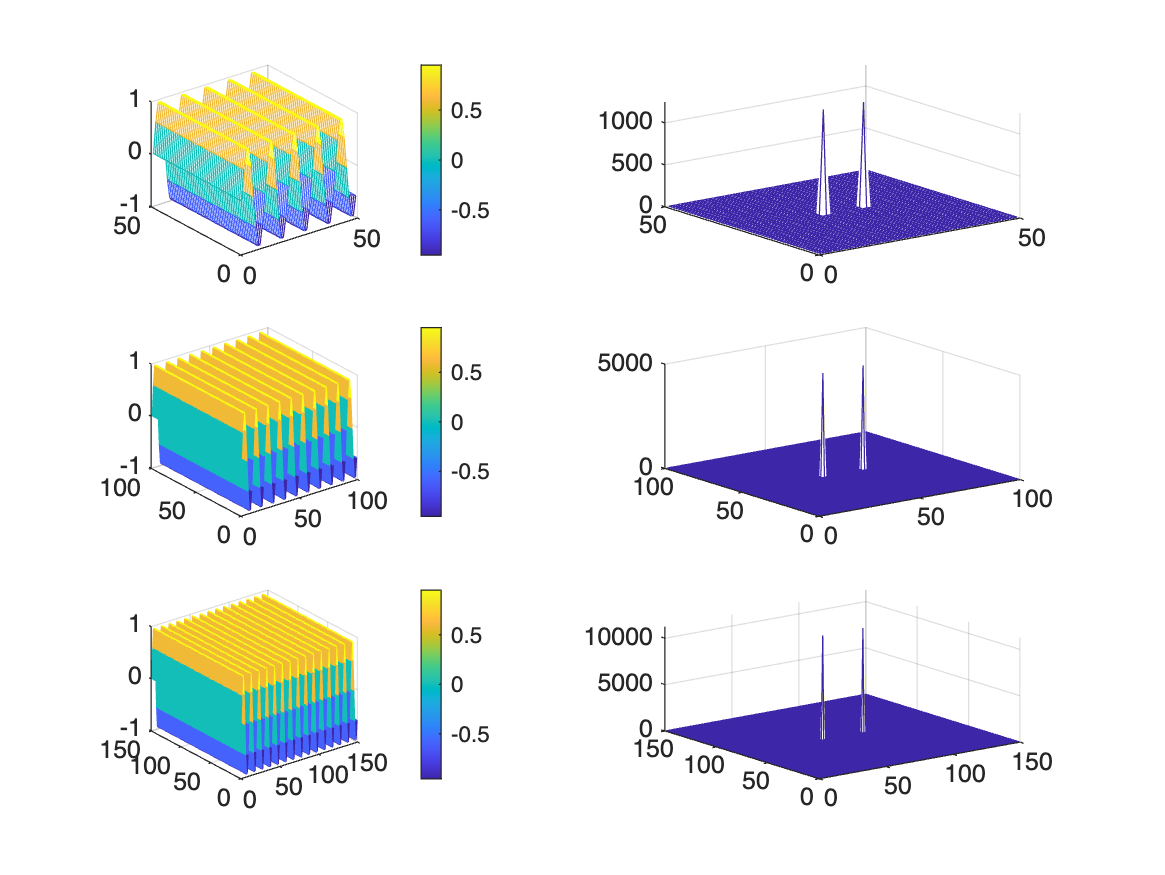

% from provided CG2DFT.m
N1 = 5; % Number of cycles in the sin wave
N2 = 10;
N3 = 15;
Step=0.1; % Resolution

NN1=N1/Step;
x1=sin(2*pi*[0:Step:N1-Step]);
xx1=zeros(NN1,NN1);
for i=1:NN1
xx1(i,:)=x1;
end

NN2=N2/Step;
x2=sin(2*pi*[0:Step:N2-Step]);
xx2=zeros(NN2,NN2);
for i=1:NN2
xx2(i,:)=x2;
end

NN3=N3/Step;
x3=sin(2*pi*[0:Step:N3-Step]);
xx3=zeros(NN3,NN3);
for i=1:NN3
xx3(i,:)=x3;
end

subplot(3,2,1)
XX1=fft2(xx1);
mesh(xx1);
colorbar;
subplot(3,2,2)
mesh(abs(fftshift(XX1)));

XX2=fft2(xx2);
subplot(3,2,3)
mesh(xx2);
colorbar;
subplot(3,2,4)
mesh(abs(fftshift(XX2)));

XX3=fft2(xx3);
subplot(3,2,5)
mesh(xx3);
colorbar;
subplot(3,2,6)
mesh(abs(fftshift(XX3)));

2) Slide B: Create these three shapes in MATLAB or Python, find their Fourier transforms, and verify whether the Fourier transforms shown on  the right are correct. - 10 points

Rectangle

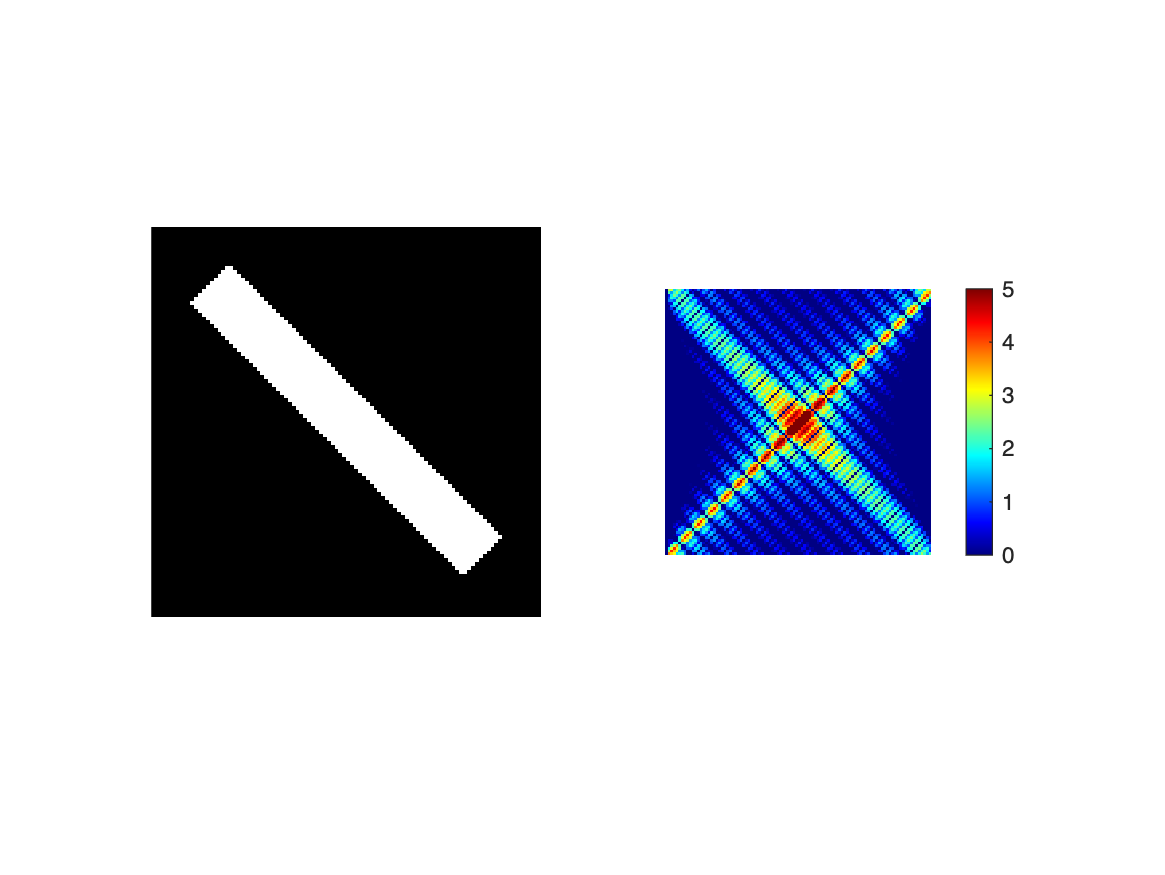

rect = poly2mask([10 20 90 80], [20 10 80 90], 100, 100);

rect_img = subplot(1,2,1);
imshow(rect)
colormap(rect_img, gray)

rect_ft = subplot(1,2,2);
F = fft2(rect);
F2 = log(abs(fftshift(F)));
imshow(F2, [0 5], "InitialMagnification","fit");
colormap(rect_ft, jet); colorbar

Generally the shape matches the one shown on the class slides, however because the width of our rectangle is thinner, the resulting FT color map has a thinner band diagonally. 

Circle

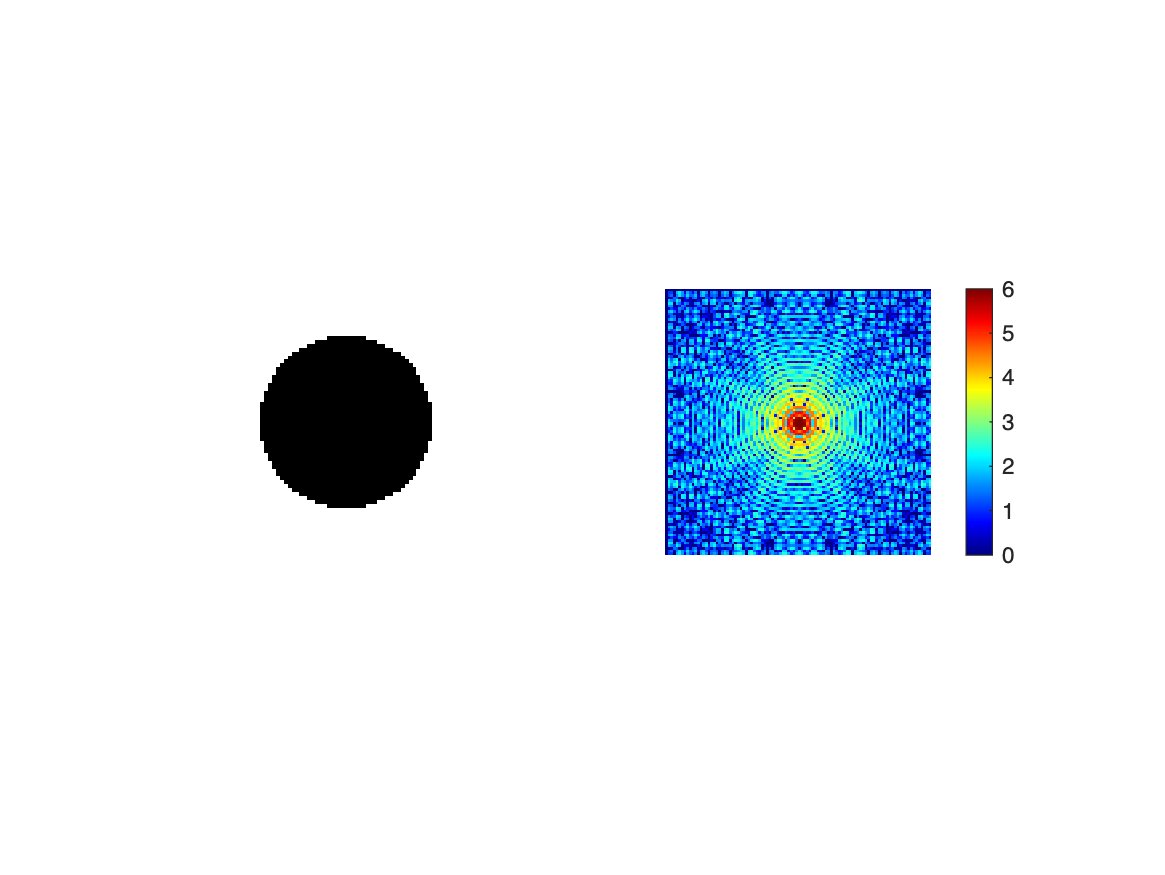

%%Make circle 
th = linspace(0,2*pi) ;
R = 5 ;  % Radius of circle 
C = [0 0] ; % Center of circle 
xc = C(1)+R*cos(th) ; yc = C(2)+R*sin(th) ;
%%Make mesh
N = 100 ;
x = C(1)+linspace(-R,R,N) ;
y = C(2)+linspace(-R,R,N) ;
[X,Y] = meshgrid(x,y) ;
Z = (X.^2+Y.^2) ;
%%Make matrix
iwant = zeros(size(Z)) ;
iwant(Z<=R) = 1 ;
iwant = imcomplement(iwant);

circle_img = subplot(1,2,1);
imshow(iwant)
colormap(circle_img, gray)


circle_ft = subplot(1,2,2);
F3 = fft2(iwant);
F4 = log(abs(fftshift(F3)));
imshow(F4, [0 6], "InitialMagnification","fit");
colormap(circle_ft, jet); colorbar

The general shape matches, but our FT color map has more radiating lines coming out from the center, and more variation on the corner. This might be caused by the rough edge of the circle image we created due to low resolution.

Cross

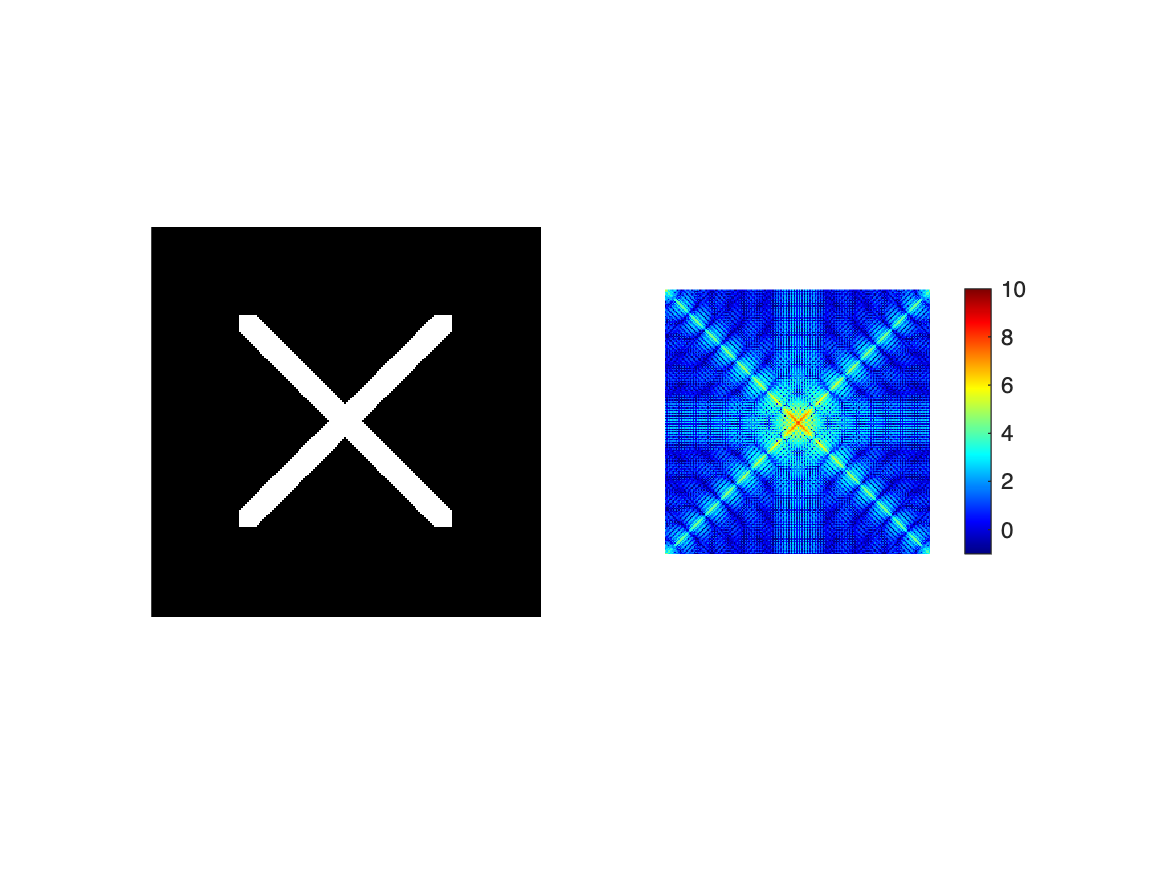

ex = zeros(200,200);

for exx = 50:150
    for eyy = 50:150
        if abs(exx-100) == abs(eyy-100)
            ex(exx-4:exx+4,eyy-4:eyy+4) = 1;
        end
    end
end


cross_img = subplot(1,2,1);
imshow(ex)
colormap(cross_img, gray)

cross_ft = subplot(1,2,2);
F5 = fft2(ex);
F6 = log(abs(fftshift(F5)));
imshow(F6, [-1 10], "InitialMagnification","fit");
colormap(cross_ft, jet); colorbar

Generally matches to the class slides. Except our FT color map has thinner bands and a faint vertical cross in addition to the diagonal lines, as a result to the tapered edges of the cross. 

3) Use an image of your choice, plot its Fourier transform. Comment  on whether interpreting the Fourier Transform was intuitive. - 10  points. 

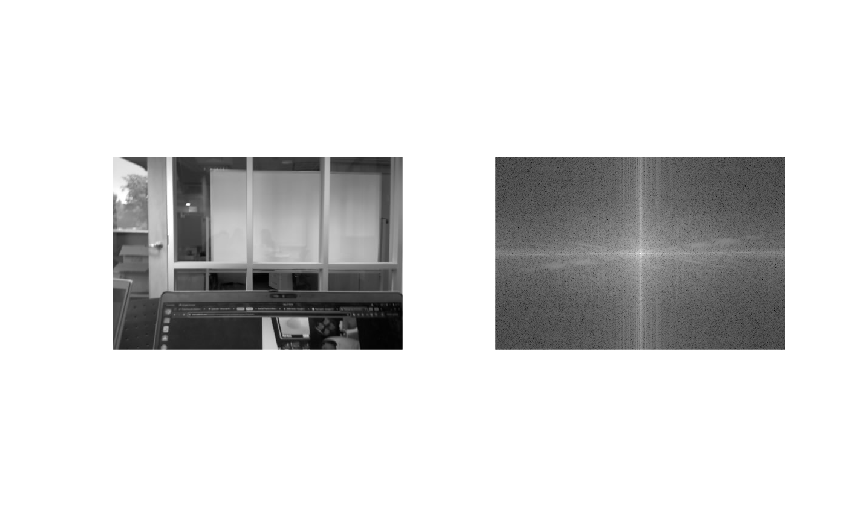

I = imread("../images/IMAGE004.jpg");
Ig = im2gray(I);

subplot(1,2,1);
imshow(Ig);

Y = fft2(Ig);
Y1 = abs(Y);
Y2 = log(abs(Y));
Y3 = log(abs(fftshift(Y)));

subplot(1,2,2);
% imtool(Y1,[]);
% imtool(Y2,[]);
imshow(Y3,[]);

The Fourier transform was intuitive. Our image has many vertical and horizontal lines from the window panes, and this is reflected in the clear cross in the Fourier transform.